clear, clc, close all;

**1 часть работы**

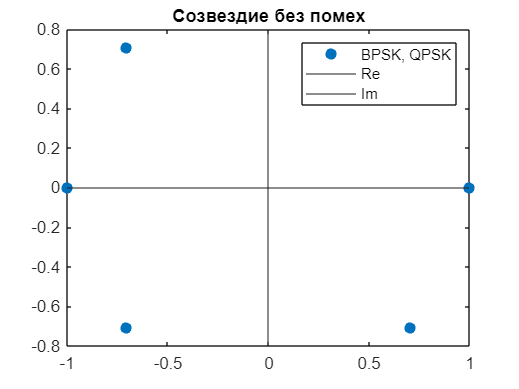

% Генерация m-последовательности и сигнала
init_seed = [1, 0, 1, 0, 1, 0, 1];  % fixed initial registers state
r = 7;
seq_length = 2^r - 1;
msequence = M_sequence(init_seed, seq_length);
rng(1)

LH=seq_length; % Длина m-последовательности
LD=10 * LH; % Длина данных
TX_header = mapping(msequence, "BPSK");
data = randi([0 1], 1, LD);
TX_data = mapping(data, "QPSK");
Frame = [TX_header TX_data];
% Frame = repmat(Frame, 1, 2);
plot(real(Frame),imag(Frame),".", 'MarkerSize', 20);
xline(0);
yline(0);
legend("BPSK, QPSK", 'Re', 'Im');
title("Созвездие без помех");


% MATCHED FILTERING (root raised cosine filter)
rolloff = 0.25;     % Rolloff factor 
span = 20;           % Filter span in symbols 
sps = 2;            % Samples per symbol 
b = rcosdesign(rolloff, span, sps);
Frame = repmat(Frame, 1, 2);
TX_IQ = upfirdn(Frame, b, sps).';

% Задержка STO через блок dsp.VariableFractionalDelay
filterLength = 20;

int_part = 2 * filterLength;
frac_part = 0.5;
STO = int_part + frac_part;

vfd = dsp.VariableFractionalDelay(InterpolationMethod="FIR", FilterHalfLength=filterLength,...
    MaximumDelay=100);
TX_IQ_delayed = vfd(TX_IQ, STO);

reset(vfd);

% Согласованный фильтр на приемнике
RX_IQ = upfirdn(TX_IQ_delayed, b, 1);

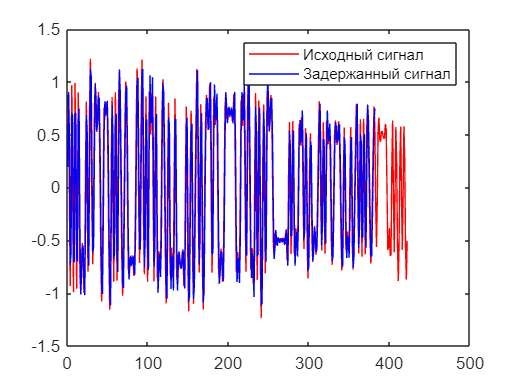

% Иллюстрация дробно-временной задержки (на действительной части символов)

plot(real(TX_IQ(span:ceil(end/7))), 'Color', 'r')
hold on
plot(real(TX_IQ_delayed(filterLength+int_part:ceil(end/7))), 'Color', 'blue')
hold off
legend('Исходный сигнал', 'Задержанный сигнал')

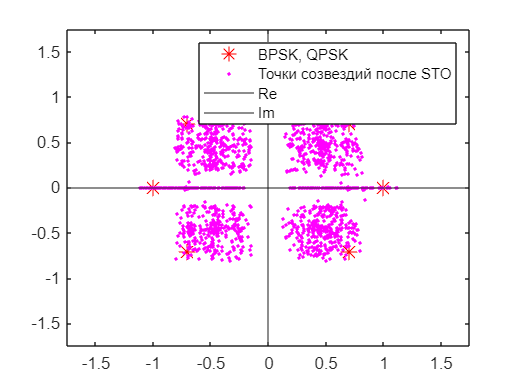

% Помехи в созвездиях (QPSK, BPSK)

plot(real(Frame(span:end)), imag(Frame(span:end)), "*", 'Color', 'red', 'MarkerSize', 10)
hold on
plot(real(TX_IQ_delayed(filterLength+int_part:end)), imag(TX_IQ_delayed(filterLength+int_part:end)), ".", 'Color', 'magenta')
hold off

axis([-1.75 1.75 -1.75 1.75]);
xline(0);
yline(0);
legend('BPSK, QPSK', 'Точки созвездий после STO', 'Re', 'Im')

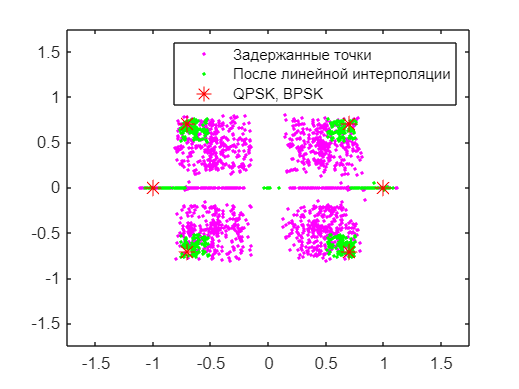

% Линейная интерполяция
mu = frac_part;
RX_IQ_linear_interpolated = interpol(RX_IQ, mu, "linear_interpol");

plot(real(TX_IQ_delayed(filterLength+int_part:end)), imag(TX_IQ_delayed(filterLength+int_part:end)), ".", 'Color', 'magenta')
hold on

% Децимация (с sps отсчетов на символ на 1)
even_indices = mod(1:length(data), sps) == 0;
decimated_linear_RX_IQ = RX_IQ_linear_interpolated(even_indices);
plot(real(decimated_linear_RX_IQ(1:end)), imag(decimated_linear_RX_IQ(1:end)), ".", 'Color', 'green')
hold on
plot(real(Frame(span:end)), imag(Frame(span:end)), "*", 'Color', 'red', 'MarkerSize', 10)
hold off

axis([-1.75 1.75 -1.75 1.75]);
legend('Задержанные точки', 'После линейной интерполяции', 'QPSK, BPSK')

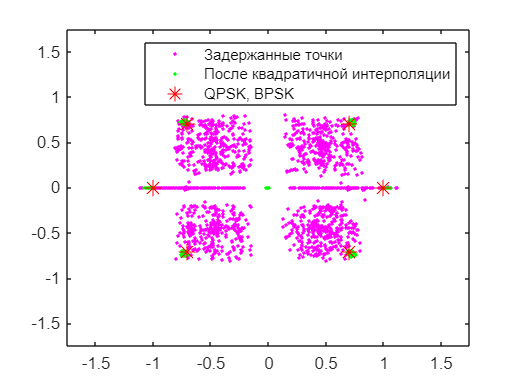

% Квадратичная интерполяция
RX_IQ_quadro_interpolated = interpol(RX_IQ, mu, "quadro_interpol");

plot(real(TX_IQ_delayed(filterLength+int_part:end)), imag(TX_IQ_delayed(filterLength+int_part:end)), ".", 'Color', 'magenta')
hold on

% Децимация (с sps отсчетов на символ на 1)
even_indices = mod(1:length(data), sps) == 0;
decimated_quadro_RX_IQ = RX_IQ_quadro_interpolated(even_indices);
plot(real(decimated_quadro_RX_IQ(1:end)), imag(decimated_quadro_RX_IQ(1:end)), ".", 'Color', 'green')
hold on
plot(real(Frame(span:end)), imag(Frame(span:end)), "*", 'Color', 'red', 'MarkerSize', 10)
hold off

axis([-1.75 1.75 -1.75 1.75]);
legend('Задержанные точки', 'После квадратичной интерполяции', 'QPSK, BPSK')

**2 часть работы**

% Реализуем Lee TED (feedforward архитектура)
L = floor(length(RX_IQ) / 3);
pred_time1 = Lee_TED(RX_IQ, sps, L);
disp(["Предсказанное время с помощью TED Lee: ", pred_time1]);

    "Предсказанное время с помощью TED Lee: "    "0.4997"




% Реализуем Oerder and Meyr TED (feedforward архитектура)
pred_time2 = Oerder_Meyr_TED(RX_IQ, L);
disp(["Предсказанное время с помощью TED Lee: ", pred_time2]);

    "Предсказанное время с помощью TED Lee: "    "0.44386"



Data = zeros(10, 101);
count = 1

count = 1

for SNR = 1 : 10
    IQ_noised = NoiseGenerator(TX_IQ, SNR);
    time_predictions = []
    for frac_part = -0.5 : 0.01 : 0.5
        STO = int_part + frac_part;
        vfd = dsp.VariableFractionalDelay(InterpolationMethod="FIR", FilterHalfLength=filterLength,...
            MaximumDelay=100);
        TX_IQ_delayed = vfd(IQ_noised, STO);
        reset(vfd);
        % Согласованный фильтр на приемнике
        RX_IQ = upfirdn(TX_IQ_delayed, b, 1);
        pred_time = Lee_TED(RX_IQ, sps, L);
        time_predictions = [time_predictions pred_time];
    end
    Data(count, :) = time_predictions;
    count = count + 1
end


time_predictions =

     []



count = 2


time_predictions =

     []



count = 3


time_predictions =

     []



count = 4


time_predictions =

     []



time_shift = -0.5 : 0.01 : 0.5;
for i = 1 : 10
    plot(time_shift, Data(i, :));
    hold on
end
legend('SNR = 1 dB', 'SNR = 2 dB', 'SNR = 3 dB', 'SNR = 4 dB', 'SNR = 5 dB', 'SNR = 6 dB', 'SNR = 7 dB', 'SNR = 8 dB', 'SNR = 9 dB', 'SNR = 10 dB')
grid on;

% Зависимость предсказанного значения от длины окна L
Times = zeros(1, length(20 : length(RX_IQ) / 4));
count = 1;
for L = 20 : length(RX_IQ) / 4
    t_pred = Lee_TED(RX_IQ, sps, L);
    Times(count) = t_pred;
    count = count + 1;
end

window_par = 20 : length(RX_IQ) / 4;
plot(window_par, Times);
xlabel("Длина окна от начала сигнала, L");
ylabel("Значение временного сдвига, t");
title("Lee TED");
grid on

clear, clc;

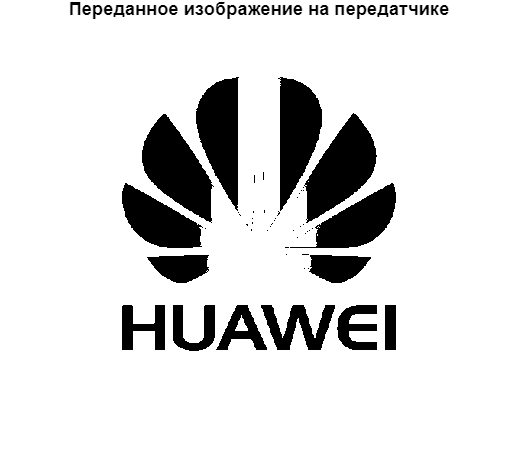

% Построим графики BER(SNR) для системы связи с постоянным STO
I = imread('huawei_logo.jpg'); 
bin_img = im2bw(I, 0.7);
imshow(bin_img);
title('Переданное изображение на передатчике');

bit_signal = reshape(bin_img, 1, size(bin_img, 1) * size(bin_img, 2));
const_type = "QPSK";
data = mapping(bit_signal, const_type);

% MATCHED FILTERING (root raised cosine filter)
rolloff = 0.25;     % Rolloff factor 
span = 20;           % Filter span in symbols 
sps = 2;            % Samples per symbol 
b = rcosdesign(rolloff, span, sps);
data = repmat(data, 1, 2);
TX_IQ = upfirdn(data, b, sps).';

% Канал связи
BERS = zeros(1, length(-20 : 0.25 : 20));
ind = 1;
% RX_bit = zeros(length(bit_signal));
for SNR = -20 : 0.25 : 20
    TX_IQ_noised = NoiseGenerator(TX_IQ', SNR);

    % Задержка STO через блок dsp.VariableFractionalDelay
    filterLength = 20;

    int_part = 2 * filterLength;
    frac_part = 0.5;
    STO = int_part + frac_part;
    
    vfd = dsp.VariableFractionalDelay(InterpolationMethod="FIR", FilterHalfLength=filterLength,...
        MaximumDelay=100);
    TX_IQ_noised_delayed = vfd(TX_IQ_noised', STO);
    
    reset(vfd);
    
    % Согласованный фильтр на приемнике
    RX_IQ = upfirdn(TX_IQ_noised_delayed, b, 1);  
    % Произведем символьную синхронизацию, используя TED Lee для feedforward
    L = floor(length(RX_IQ) / 4);  % Оцениваем параметр окна исходя из предыдущего графика для Lee TED на других данных
    time_shift = Lee_TED(RX_IQ, sps, L);
    RX_IQ_interpol = interpol(RX_IQ, time_shift, 'quadro_interpol');
    
    % Децимация (с sps отсчетов на символ на 1)
    even_indices = mod(1:length(data), sps) == 0;
    decimated_quadro_RX_IQ = RX_IQ_interpol(even_indices);

    % Получим исходные биты на выходе демаппера и оценим BER
    RX_bit = demapping(decimated_quadro_RX_IQ, const_type);
    BER = Error_check(bit_signal, RX_bit);
    BERS(ind) = BER(2);
    ind = ind + 1;
end

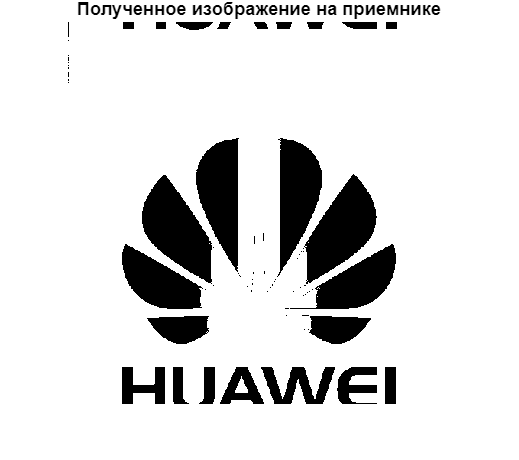

% Выведем полученное изображение
reciever_img = reshape(RX_bit, size(bin_img));
imshow(reciever_img);
title('Полученное изображение на приемнике');

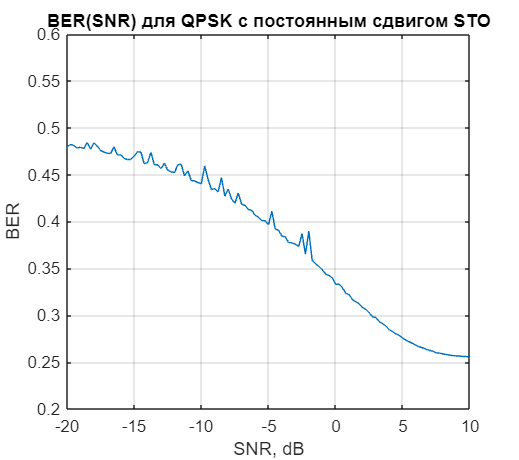

% Построим график BER(SNR)
SNRs = -20 : 0.25 : 20;
plot(SNRs, BERS);
ylim([0.2, 0.6]);
xlim([-20, 10]);
grid on;
xlabel('SNR, dB');
ylabel('BER');
title('BER(SNR) для QPSK c постоянным сдвигом STO');

% Построим график BER(SNR) для системы без рассинхронизации
BERS2 = zeros(1, length(-20 : 0.25 : 20));
ind = 1;
for SNR = -20 : 0.25 : 20
    TX_IQ_noised = NoiseGenerator(TX_IQ', SNR);

    % Согласованный фильтр на приемнике
    RX_IQ = upfirdn(TX_IQ_noised, b, 1)';  
    
    % Децимация (с sps отсчетов на символ на 1)
    even_indices = mod(1:length(data), sps) == 0;
    decimated = RX_IQ(even_indices);

    % Получим исходные биты на выходе демаппера и оценим BER
    RX_bit = demapping(decimated, const_type);
    BER2 = Error_check(bit_signal, RX_bit);
    BERS2(ind) = BER2(2);
    ind = ind + 1;
end

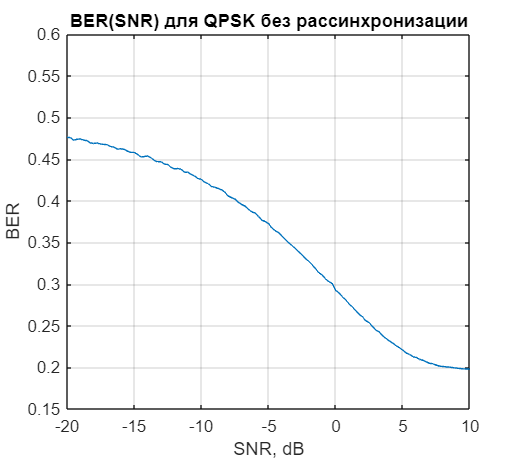

% Построим график BER(SNR)
SNRs = -20 : 0.25 : 20;
plot(SNRs, BERS2);
ylim([0.15, 0.6]);
xlim([-20, 10]);
grid on;
xlabel('SNR, dB');
ylabel('BER');
title('BER(SNR) для QPSK без рассинхронизации');